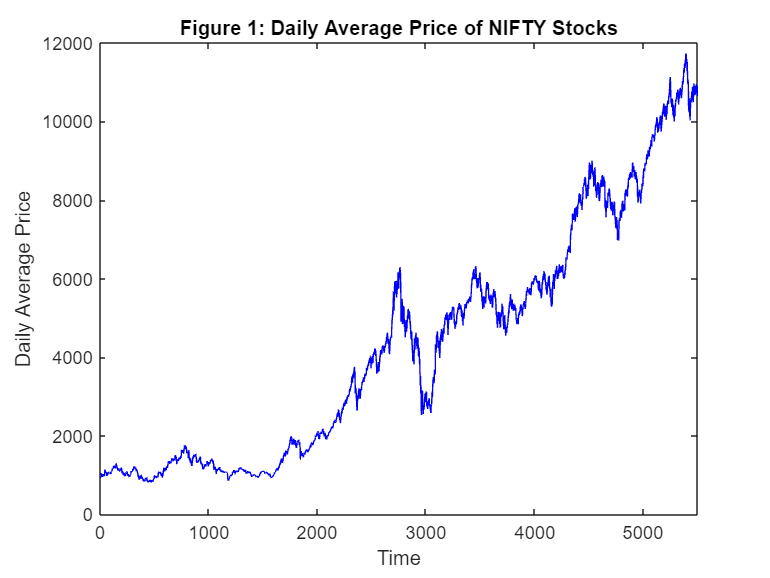

% Load Data
price_data = load('price.dat');
fluct_data = load('fluct.dat');
gauss_data = load('gauss.dat');
wiene_data = load('wiene.dat');
trade_data = load('trade.dat');

% Plotting Figure 1
figure;
plot(price_data(:, 2), price_data(:, 3), 'b'); % assuming time vs. daily average price
xlabel('Time');
ylabel('Daily Average Price');
xlim([0 5500]);
title('Figure 1: Daily Average Price of NIFTY Stocks');

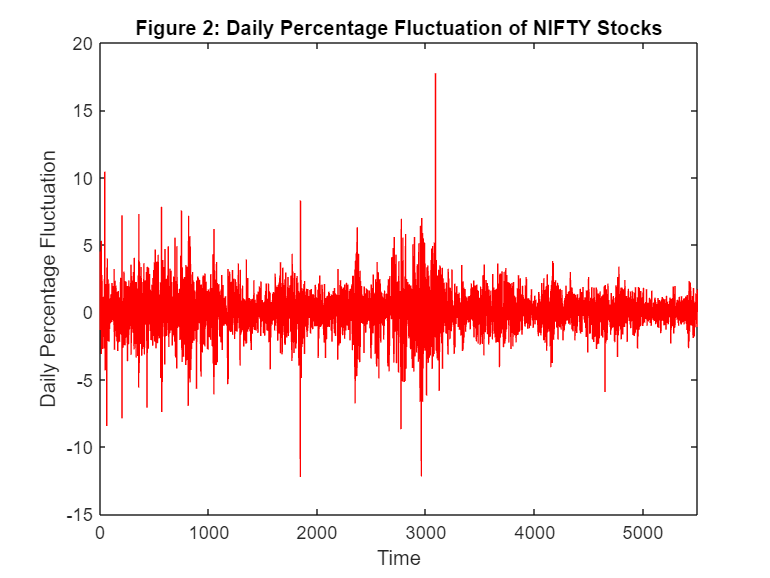



% Plotting Figure 2
figure;
plot(fluct_data(:, 2), fluct_data(:, 3), 'r'); % assuming time vs. daily percentage fluctuation
xlabel('Time');
ylabel('Daily Percentage Fluctuation');
xlim([0 5500]);
title('Figure 2: Daily Percentage Fluctuation of NIFTY Stocks');

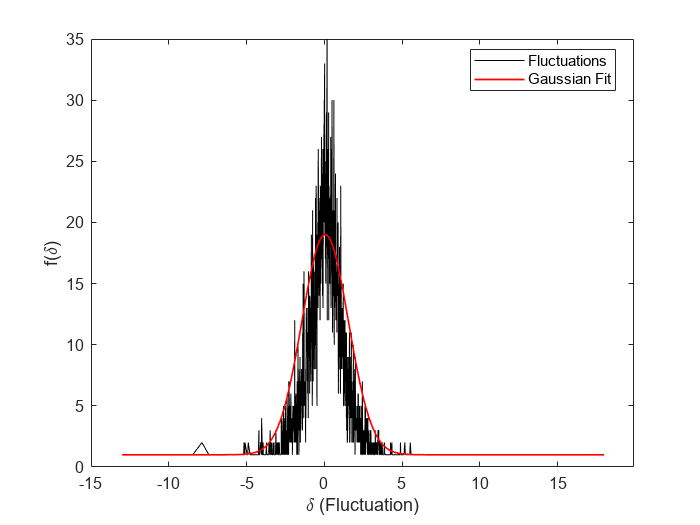

t = readtable('gauss.dat');

plot(t{:,2}, t{:,3},'k',LineWidth=0.5);
sigma = 1.495;
mu = 0.057;
f0 = 18;
del = -13:0.01:18;
%legend('Price of Nifty', 'Analytical value of Nifty', 'Location', 'best');
f = 1 + f0.* exp( (-(del - mu).^2)./(2*sigma*sigma) );
hold on;
plot(del, f,'r', 'LineWidth', 1);
legend('Fluctuations', 'Gaussian Fit', 'Location', 'best');
xlabel('\delta (Fluctuation)');
ylabel('f(\delta)');

hold off;

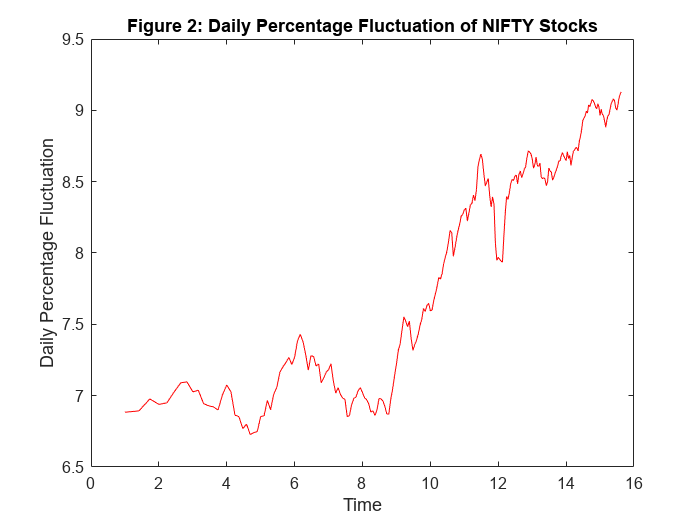




figure;
plot(wiene_data(:, 2), wiene_data(:, 3), 'r'); % assuming time vs. daily percentage fluctuation
xlabel('Time');
ylabel('Daily Percentage Fluctuation');
title('Figure 2: Daily Percentage Fluctuation of NIFTY Stocks');

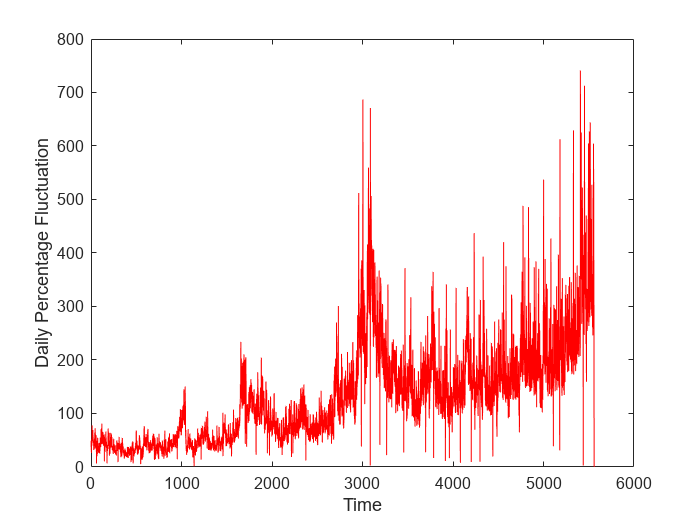


figure;
plot(trade_data(:, 2), trade_data(:, 3), 'r'); % assuming time vs. daily percentage fluctuation
xlabel('Time');
ylabel('Daily Percentage Fluctuation');